# $\epsilon(z)$` synthesis from `$\Gamma(\omega, z)\Big|_{z=0}$

`The line is as follows`

- `L = 200 `$\mu$

- 
$$Z_L = 70 + j\omega 3\times10^9 \Omega$$


- 
$$R_g=50 \Omega$$


- `W = S = 20 `$\mu$

- 
$$L_{strip} = 3 \mu$$


- 
$$S_{strip} = 1\mu$$


- 
$$W_{strip} = 30\mu$$


clear all;
L = 200e-6;
W = 20e-6;
S = W;
Lstrip = 3e-6;
Sstrip = 1e-6;
Wstrip = 30e-6;

Rg = 50; % omega

`We have`


$$\Gamma(\omega, z)=\frac{Z_L-Z(\omega, z)}{Z_L+Z(\omega,z)}$$


`We also want that `$Z(\omega, L) = Z_L$

`Assume we are given that `$\Gamma(\omega, z)\Big|_{z=0}$` is a low pass chebyshev's filter`

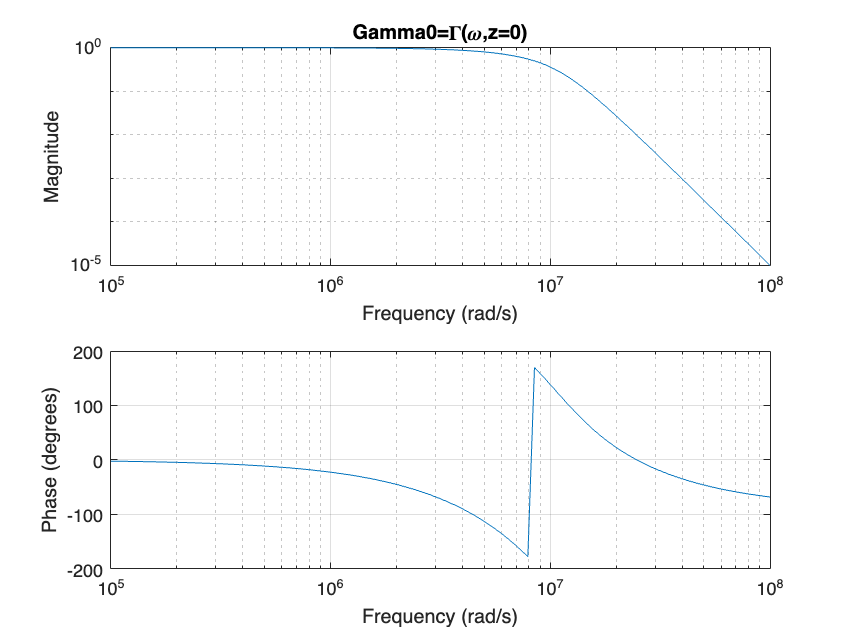

[b,a] = besself(5,1e7);
figure;
freqs(b,a, 1e2)
title("Gamma0=\Gamma(\omega,z=0)")

[Gamma0,w] = freqs(b,a,1e2);

`Now that `$\omega$` is defined, we can define `$Z_L$

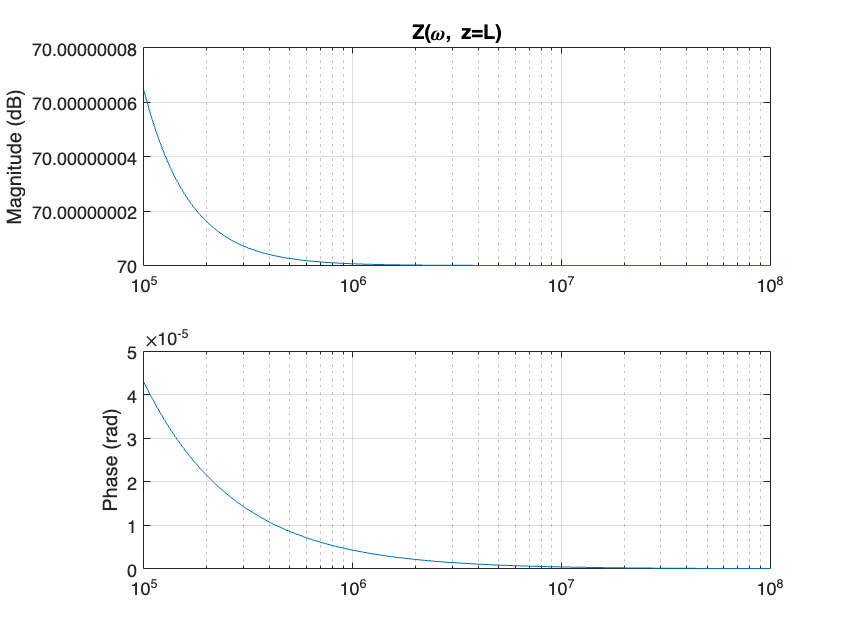

ZL = 70 + 3e2*1j./w;
figure;
subplot(2, 1, 1)
semilogx(w, abs(ZL))
title("Z(\omega, z=L)")
ylabel("Magnitude (dB)")
grid("on")
subplot(2, 1, 2)
semilogx(w, angle(ZL))
ylabel("Phase (rad)")
grid("on")

`Using `$\Gamma(\omega, 0)$`, we can find `$Z(\omega, 0)$` given by Z0`


$$\Gamma(\omega, 0)=\frac{R_g-Z(\omega, 0)}{R_g+Z(\omega,0)}\to  Z(\omega, 0)=R_g\frac{1-\Gamma(\omega, 0)}{1+\Gamma(\omega, 0)}$$
 

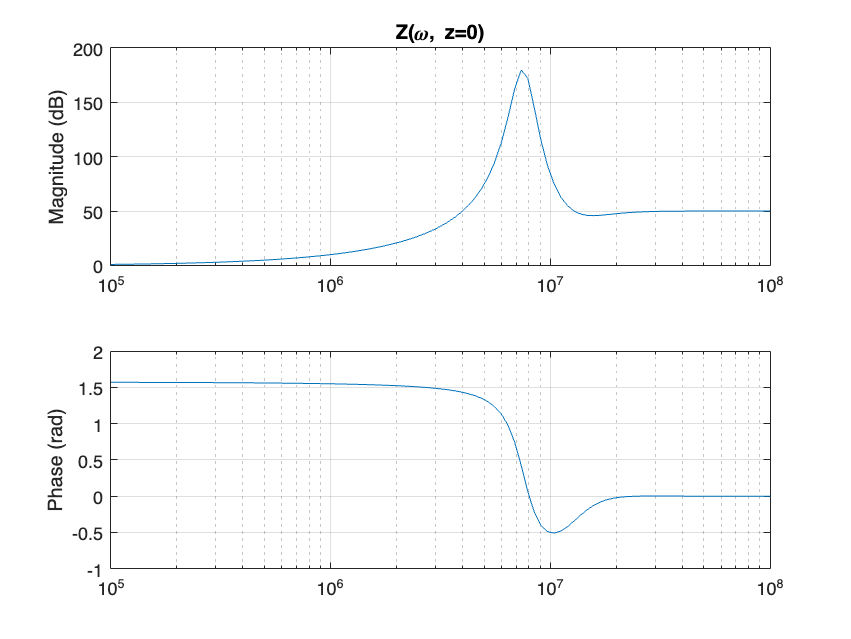

Z0 = Rg.*((1-Gamma0)./(1+Gamma0));
figure;
subplot(2, 1, 1)
semilogx(w, abs(Z0))
title("Z(\omega, z=0)")
ylabel("Magnitude (dB)")
grid("on")
subplot(2, 1, 2)
semilogx(w, angle(Z0))
ylabel("Phase (rad)")
grid("on")

fprintf("rad(Z0) = [%d, %d, ]", min(angle(Z0)), max(angle(Z0)));

rad(Z0) = [-5.075895e-01, 1.568609e+00, ]